# Week 3

Stephen Cruz Wright 

Vladislav Serafimov

## Signal analysis

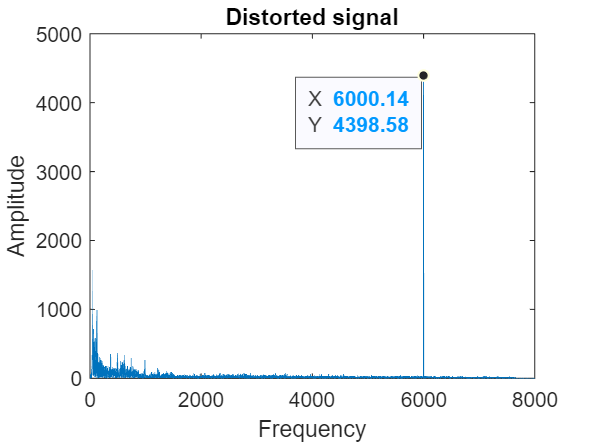

[x, fs] = audioread("week3_sample_dist.wav");
fy = fft(x);
f = linspace(0,fs, length(fy));
plot(f, abs(fy))
xlim([0 8000])
title("Distorted signal")
xlabel("Frequency")
ylabel("Amplitude")

figure

## Low-pass filter design

Given $f_c = \frac{1}{2}f_{int}$

And $\omega_c = \frac{1}{\tau} => f_c = \frac{1}{2\pi\tau}
$


$$\tau= \frac{1}{\pi f_{int}} $$


We can determine the resistor and capacitor values needed with


$$\tau = \frac{1}{2\pi f_{int}} = \frac{1}{6000}$$


The transfer function used is taken from W3's presentation

The difference equation can be derived as follows


$$H = \frac{1 - e^{\frac{-1}{f_s\tau}}}{z - e^{\frac{-1}{f_s\tau}}}$$


Which we need to shift by $z^{-1}$


$$\frac{Y}{X} = \frac{z^{-1}(1 - e^{\frac{-1}{f_s\tau}})}{1 - z^{-1}e^{\frac{-1}{f_s\tau}}}$$



$$(X)(z^{-1} - z^{-1}e^{\frac{-1}{f_s\tau}}) =(Y)({1 - z^{-1}e^{\frac{-1}{f_s\tau}})$$



$$y_n  = 0,6921.x_{n-1}
+ 0,3079.y_{n - 1} $$


## Filtering

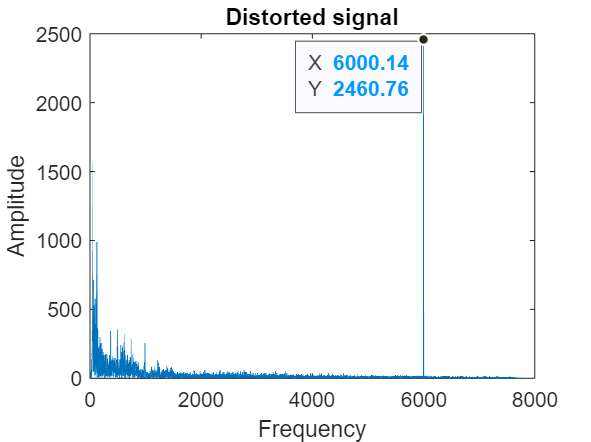

clear
[x, fs] = audioread("week3_sample_dist.wav");
y = zeros(1, 44000);
f = linspace(0,fs, length(x));
for k = 2:length(x)
    y(k) = x(k - 1).*0.6921 + y(k - 1).*0.3079;
end
fy = fft(y);
sound(y, fs)
plot(f, abs(fy))
xlim([0 8000])
title("Filtered signal")
xlabel("Frequency")
ylabel("Amplitude")

ax = gca;
chart = ax.Children(1);
datatip(chart,6000,2461);
figure

## Comparison

### 1.

The original signal's amplitude is 4398,58. After the last loop it goes down to 2460,76. This means that the attenuation in dB is $A_{dB} = 20log(\frac{2460,76}{4398,58}) \approx -5,045dB$

### 2.

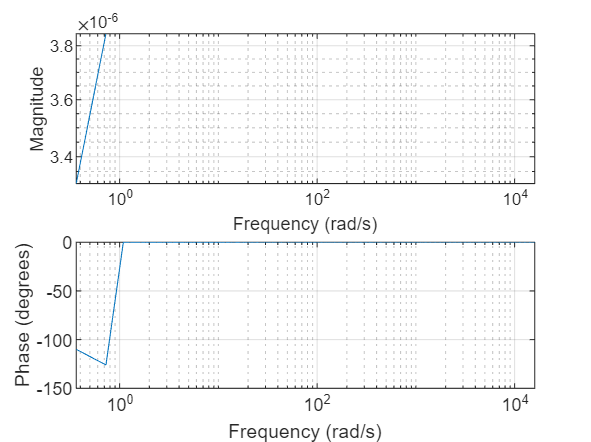

clear
[x, fs] = audioread("week3_sample_dist.wav");
fy = fft(x);
fxx = transpose(abs(fy));
tau = 1/6000;
f = linspace(0,fs, length(fy));
h1 = (1 - exp(-1./(fs.*tau)));
h2 = (1i.*2.*pi.*f - exp(-1./(fs.*tau)));
freqs(h1, h2, f)